# **TP5 - Résolution d'une équation différentielle à l'aide des transformées de Laplace**

### Exercice 31 p 26

La fonction lsim permet de simuler la réponse à une entrée u(t) quelconque

s est une varaible symbolique.

syms s;
t = 1:50;
Y = s / ((s^2 + 1)* (s^2+s+1));
ilaplace(Y) % Tranformé inverse de Laplace

$$ans = \sin\left(t\right)-\frac{2\,\sqrt{3}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3}$$

Y1 = sin(t) - (2/sqrt(3) * exp(-1/2 * t) .* sin(sqrt(3) / 2 * t))

Y1 =     0.3080    0.4900    0.0079   -0.7073   -0.8710   -0.2285    0.6646    0.9766    0.3993   -0.5494   -0.9995   -0.5342    0.4218    0.9911    0.6500   -0.2883   -0.9616   -0.7510    0.1499    0.9130    0.8367   -0.0089   -0.8462   -0.9056   -0.1324    0.7626    0.9564    0.2709   -0.6636   -0.9880   -0.4040    0.5514    0.9999    0.5291   -0.4282   -0.9918   -0.6435    0.2964    0.9638    0.7451   -0.1586   -0.9165   -0.8318    0.0177    0.8509    0.9018    0.1236   -0.7683   -0.9538   -0.2624


Autre méthode pour le faire

s2 = tf('s');
Y2 = s2 / ((s2^2 + 1)* (s2^2+s2+1));
rep1 = impulse(Y2,t); % On peut mettre en deuxième paramètre le nombre de points
rep2 = step(Y2, t);

On peut aussi utiliser le la fonction lsim qui permet de simuler la réponse à une entrée u(t) quelconqu

u = cos(t) ;
Y3 = lsim(Y2, u, t);

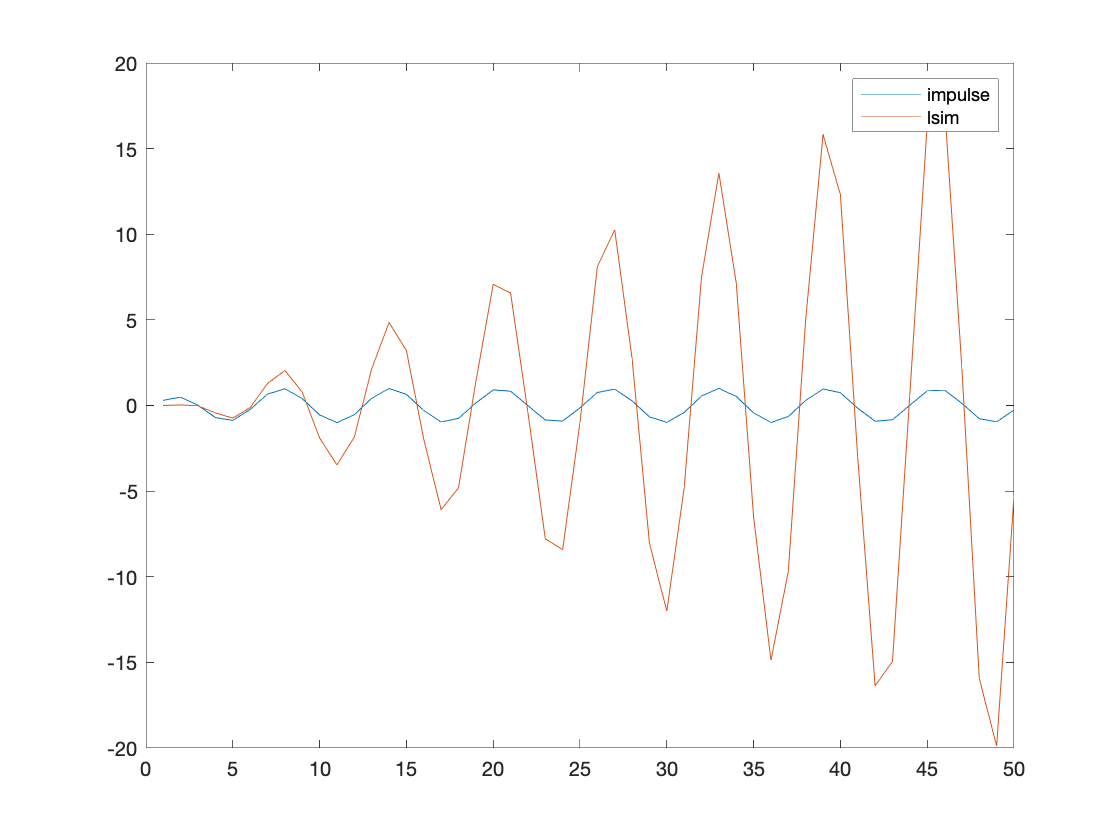

plot(t, rep1, t, Y3)
legend("impulse", "lsim")